Para la planta P(s) = 20(1− s) (1+ 2s)(1+10s) , se pide:

a) Encontrar por tanteo el período de muestreo mínimo, con resolución 0.5 s, que garantiza que la función de transferencia en tiempo discreto obtenida por discretización con retendor de orden 0 es inversamente estable (todos sus ceros están dentro del círculo unidad). Dar la función de transferencia en tiempo discreto para ese período de muestreo. 

s=tf("s")

s =
 
  s
 
Continuous-time transfer function.



Km=8.2897e-02;
Tm= 6.0718e-02;
Tf=0.18;
P = Km/(Tm*s+1)/(Tf*s+1);
Ts=0.005;
z=tf("z",Ts)

z =
 
  z
 
Sample time: 0.005 seconds
Discrete-time transfer function.



Pd=c2d (P,Ts,"zoh") %Zero order hold 

Pd =
 
  9.141e-05 z + 8.811e-05
  -----------------------
  z^2 - 1.894 z + 0.8957
 
Sample time: 0.005 seconds
Discrete-time transfer function.



pzmap(Pd)

b) En primer lugar se diseña C(z) para que la función de transferencia en lazo cerrado entre referencia y salida en tiempo discreto sea 1/z. Buscar el período de muestreo, con resolución de 0.5 s y comenzando en el valor calculado en a), para que la respuesta del sistema sea lo más rápida posible (menor tiempo de establecimiento al 5%) sin que el sobrepaso supere el 20%.

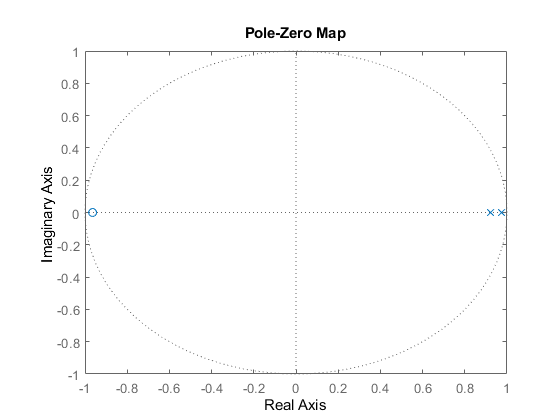

Current plot held


%F=1/z Dead beat de primer orden
ts=0.01;
Ts=ts;
% Discretizacion de la planta
Pd=c2d(P,ts,'zoh');
% Fd=Cd*Pd/(1+Cd*Pd) ==> Cd=Fd/Pd/(1-Fd)
% Funcion de transferencia de lazo cerrado
z=tf('z',ts);
Fd=1/z;
% Funcion de transferencia del control
Cd=minreal(Fd/Pd/(1-Fd));


plot(sim("Control_deadbeat_sim.slx"))
%plot(ScopeData.realtime, ScopeData.signals.values)

hold

c) A continuación se diseña C(z) para que la función de transferencia de lazo cerrado entre referencia y salida en tiempo discreto sea (z −α ) (1−α )z 2 siendo α el cero de la planta en tiempo discreto. Obtener por tanteo el periodo de muestreo, con resolución de 0.5 s y comenzando en el valor calculado en a), para que la respuesta del sistema sea lo más rápida posible sin que el sobrepaso supere el 20%.    

%F= (z −α )/(1−α )/z^2 Dead beat de segundo orden alpha es el cero de pd
%Periodo de muestreo
ts=4.5;
Ts=ts

Ts = 4.5000

% Discretizacion de la planta con nuevo ts
Pd=c2d(P,ts,'zoh');
% Ceros y polos de Pd
[zPd,pPd,kPd]=zpkdata(Pd,'v')

zPd = -7.0694e-12

pPd = 	1.0e+-10 *

         0
    0.1389


kPd = 0.0829

alfa=zPd;
% Fd=Cd*Pd/(1+Cd*Pd) ==> Cd=Fd/Pd/(1-Fd)
% Funcion de transferencia de lazo cerrado
z=tf('z',ts);
Fd=(z-alfa)/(1-alfa)/z^2;
% Funcion de transferencia del control
Cd=minreal(Fd/Pd/(1-Fd));
plot(sim("MATLAB\Tema 4\Control_deadbeat_sim.slx"))

No system or file called 'MATLAB\Tema 4\Control_deadbeat_sim.slx' found.

d) Para los controles diseñados en b) y en c), comparar el sobrepaso y el tiempo de establecimiento para escalón unitario en referencia cuando se simula la respuesta con el sistema mixto mostrado en la figura.